corrmat = zeros([size(xz_E.DataMatrix,2), size(shan_E.DataMatrix,2)])

corrmat =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i = 1:size(xz_E.DataMatrix,2)
    for j = 1:size(shan_E.DataMatrix,2)
        corrmat(i,j) = corr(xz_E.DataMatrix(:,i), shan_E.DataMatrix(:,j));
    end
end

[~,I] = max(corrmat,[], 2); %

xz_shan_E.DataMatrix = shan_E.DataMatrix(:,I);

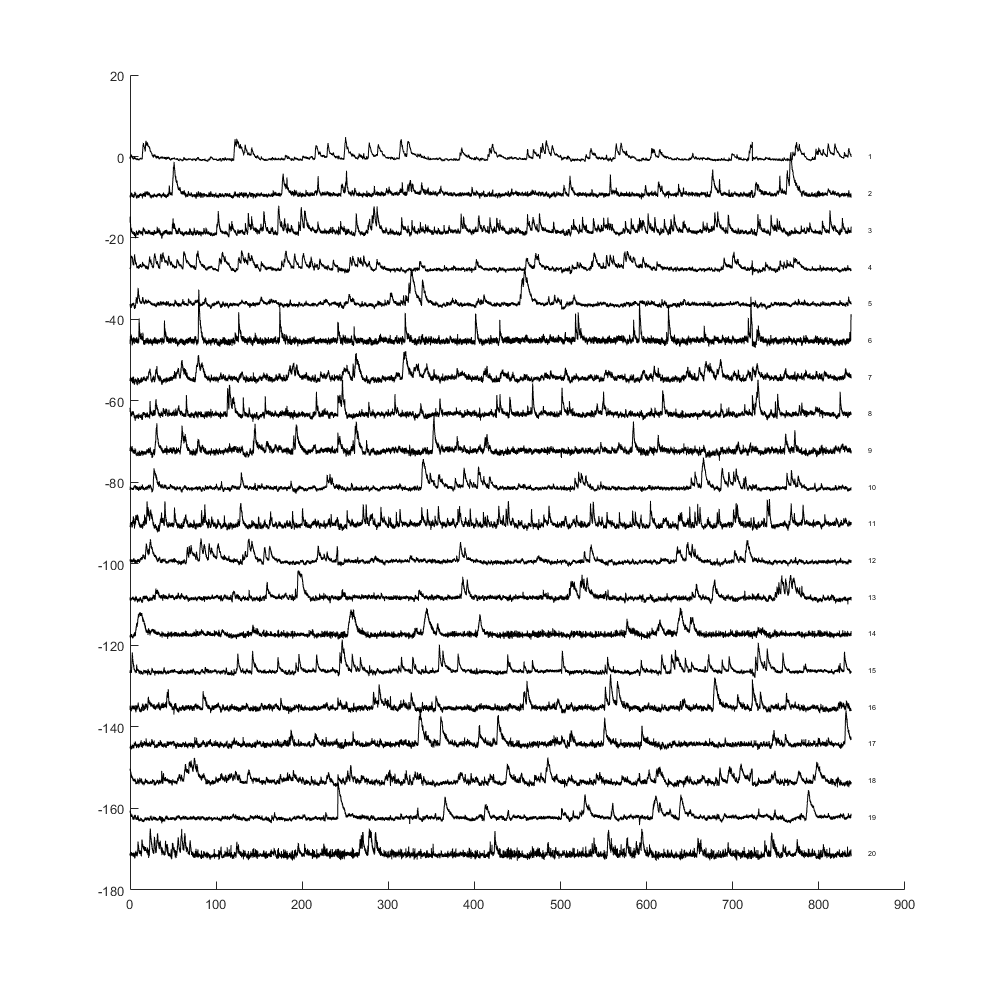

PlotSelectedCells(xz_E,1:20)

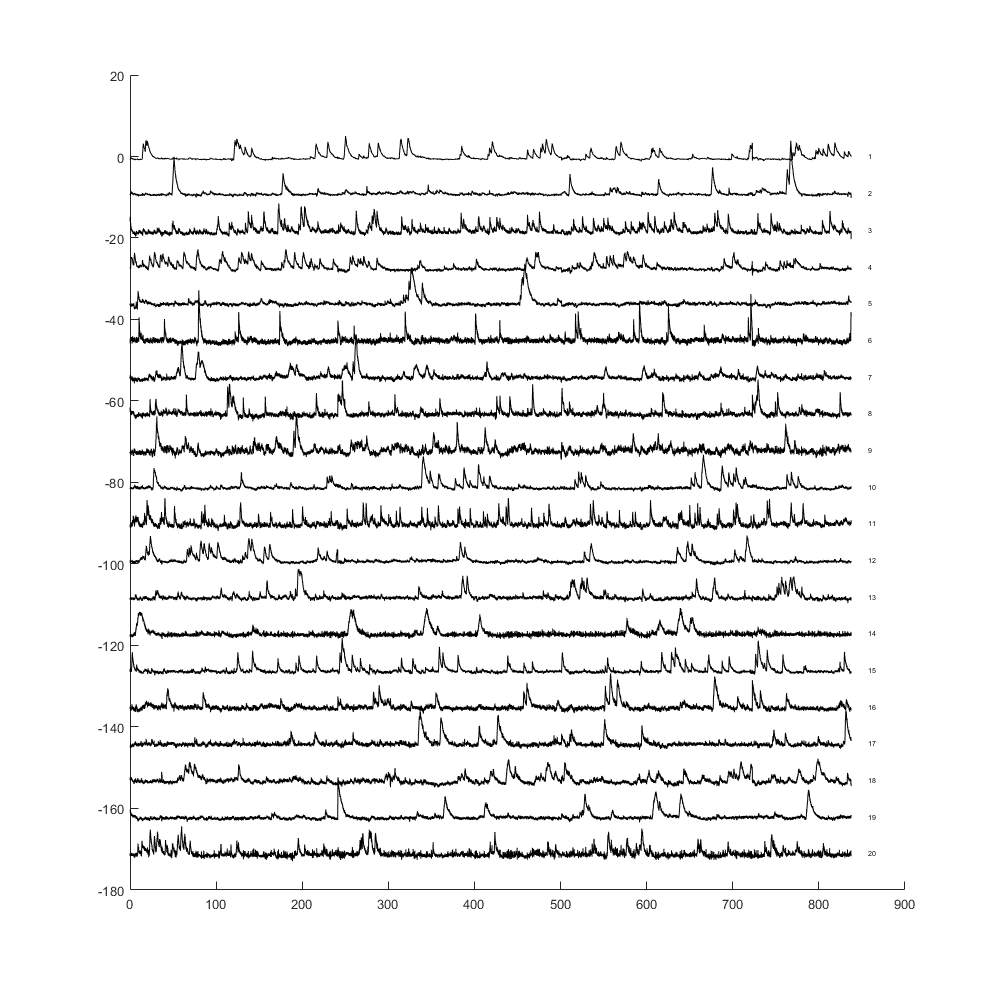

PlotSelectedCells(xz_shan_E,1:20)

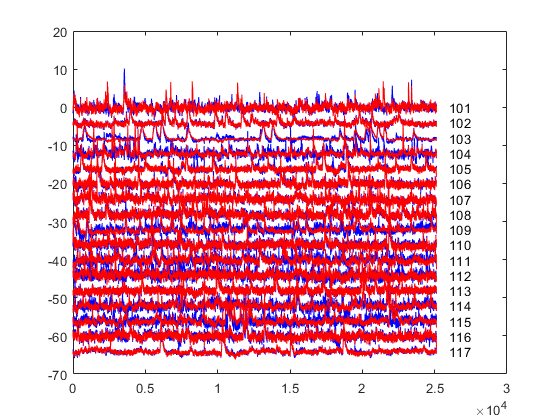

figure,
clis = 101:117;
plot(1:size(xz_E.DataMatrix,1),(zscore(xz_E.DataMatrix(:, clis)) - 4*(0:16)), 'Color','blue',"LineWidth",0.1);
hold on,
plot(1:size(xz_shan_E.DataMatrix,1),(zscore(xz_shan_E.DataMatrix(:, clis)) - 4*(0:16)), 'Color','red',"LineWidth",0.1);
for i = 1:length(clis)
    text( 2.6e4, (1-i)*4, num2str(clis(i)))
end

% simply match sh->xz and xz->sh to compare the same bunch of cells
shan_E = cell(2);
xz_E = cell(2);
load('D:\Xingjian\SH_subpop\CMK\CMK4_dTTexp1\Cam\ms.mat');
shan_E{1} = ms;
load('D:\Xingjian\SH_subpop\CMK\CMK5_dTTexp1\Cam\ms.mat');
shan_E{2} = ms;
load('D:\Xingjian\SH_subpop\CMK\CMK4_dTTexp1\Cam\XZ_run\ms.mat');
xz_E{1} = ms;
load('D:\Xingjian\SH_subpop\CMK\CMK5_dTTexp1\Cam\XZ_run\ms.mat');
xz_E{2} = ms;

xz_E{1}.FiltTraces = zscore(xz_E{1}.FiltTraces);
xz_E{1}.RawTraces = zscore(xz_E{1}.RawTraces);
xz_E{2}.FiltTraces = zscore(xz_E{2}.FiltTraces);
xz_E{2}.RawTraces = zscore(xz_E{2}.RawTraces);
shan_E{1}.FiltTraces = zscore(shan_E{1}.FiltTraces);
shan_E{1}.RawTraces = zscore(shan_E{1}.RawTraces);
shan_E{2}.FiltTraces = zscore(shan_E{2}.FiltTraces);
shan_E{2}.RawTraces = zscore(shan_E{2}.RawTraces);

cor5 = zeros([size(shan_E{1}.RawTraces,2), size(xz_E{1}.RawTraces,2)]);
cor7 = zeros([size(shan_E{2}.RawTraces,2), size(xz_E{2}.RawTraces,2)]);
for i = 1:size(cor5,1)
    for j = 1:size(cor5,2)
        cor5(i,j) = corr(shan_E{1}.FiltTraces(:,i), xz_E{1}.FiltTraces(:,j));
    end
end
for i = 1:size(cor7,1)
    for j = 1:size(cor7,2)
        cor7(i,j) = corr(shan_E{2}.FiltTraces(:,i), xz_E{2}.FiltTraces(:,j));
    end
end

[~,I5_s2z] = max(cor5,[], 1);
[~,I5_z2s] = max(cor5,[],2);
[~,I7_s2z] = max(cor7,[],1);
[~,I7_z2s] = max(cor7,[],2);

% shan-->xz
xz_glist = {find(xz_E{1}.cell_label == 1), find(xz_E{2}.cell_label==1)};

mlen = min(size(xz_E{1}.FiltTraces,1), size(xz_E{2}.FiltTraces,1));
corr(mean(xz_E{1}.FiltTraces(1:mlen,xz_glist{1}),2), mean(xz_E{2}.FiltTraces(1:mlen,xz_glist{2}),2))

ans = 0.0725

corr(mean(shan_E{1}.FiltTraces(1:mlen,I5_s2z(xz_glist{1})),2), mean(shan_E{2}.FiltTraces(1:mlen,I7_s2z(xz_glist{2})),2))

ans = 0.1089

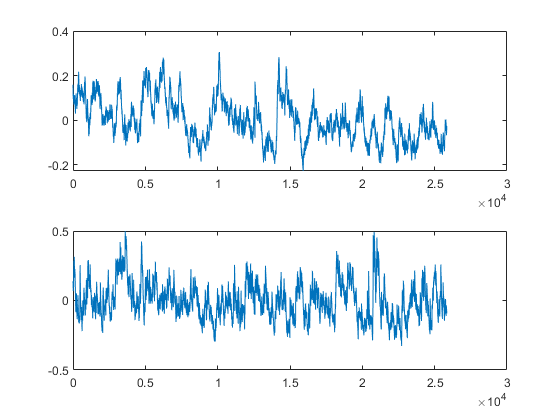

figure, subplot(2,1,1), plot(mean(xz_E{1}.FiltTraces(1:mlen,xz_glist{1}),2));
subplot(2,1,2), plot(mean(xz_E{2}.FiltTraces(1:mlen,xz_glist{2}),2));

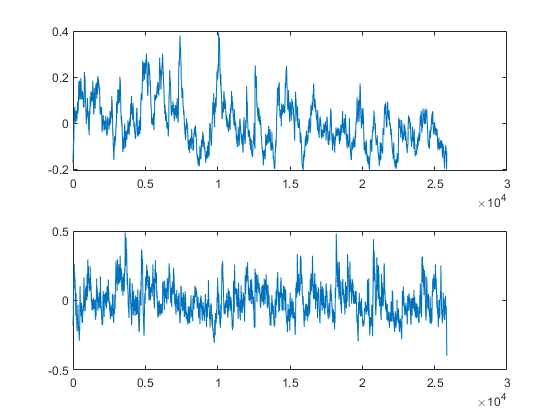

figure, subplot(2,1,1), plot(mean(shan_E{1}.FiltTraces(1:mlen,I5_s2z(xz_glist{1})),2));
subplot(2,1,2), plot(mean(shan_E{2}.FiltTraces(1:mlen,I7_s2z(xz_glist{2})),2));

%xz-->shan
corr(mean(xz_E{1}.FiltTraces(1:mlen,I5_z2s),2), mean(xz_E{2}.FiltTraces(1:mlen,I7_z2s),2))

ans = 0.1095

corr(mean(shan_E{1}.FiltTraces(1:mlen,:),2), mean(shan_E{2}.FiltTraces(1:mlen,:),2))

ans = 0.1955

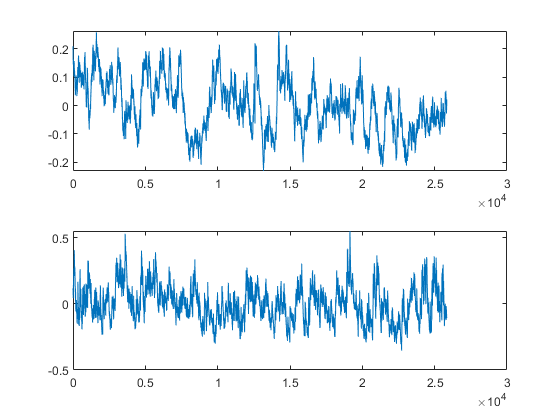

figure, subplot(2,1,1), plot(mean(xz_E{1}.FiltTraces(1:mlen,I5_z2s),2));
subplot(2,1,2), plot(mean(xz_E{2}.FiltTraces(1:mlen,I7_z2s),2));

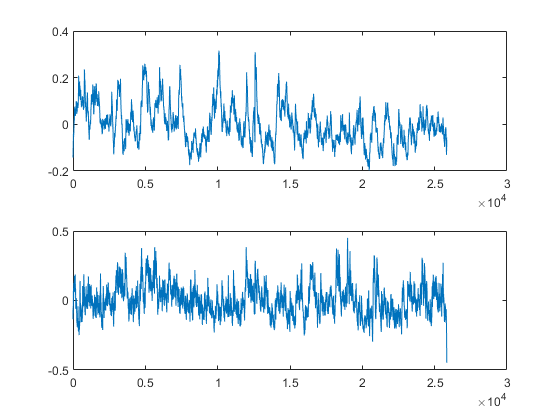

figure, subplot(2,1,1), plot(mean(shan_E{1}.FiltTraces(1:mlen,:),2));
subplot(2,1,2), plot(mean(shan_E{2}.FiltTraces(1:mlen,:),2));

corr(mean(xz_E{1}.FiltTraces(1:mlen,:),2), mean(xz_E{2}.FiltTraces(1:mlen,:2),2))

ans = 0.1064

corr(mean(shan_E{1}.FiltTraces(1:mlen,:),2), mean(shan_E{2}.FiltTraces(1:mlen,:),2))

ans = 0.1955